# Curva de Capacidad - Capability Curve

# Generador de Polos Salientes

***Nombre: *****Prof. Mauricio Santiago Soria Colina, Escuela Politécnica Nacional**

***Fecha:***** 20 de julio de 2024**

## Introducción

Se desarrolla el modelamiento de la curva de capacidad de una unidad de generación eléctrica. Se determinan las regiones de operación segura del generador sincrónico y los límites que dependen de su operación.

Es un desarrollo muy útil para las materias de Máquinas Eléctricas, Sistemas Eléctricos de Potencia y Estabilidad de Sistemas de Potencia. Está listo para ser utilizado en el aprendizaje en línea y se requiere únicamente los conocimientos esenciales de máquinas eléctricas.

Se emplea la programación en MATLAB a través de Live Script y se desarrollan gráficas explicativas de las regiones que se generan.

Finalmente, esta aplicación puede ser utilizada en el campo laboral de los operadores de las centrales de generación eléctrica para llevar a cabo una operación segura de los generadores sincrónicos de las centrales hidroeléctricas y termoeléctricas.

Palabras clave: Curva de capacidad, generador síncrono, límites de operación de plantas de generación, máquinas eléctricas, MATLAB Live Script

Keywords: Capability curve, synchronous generator, operating limits of generation plants, electric machines, MATLAB Live Script

## Objetivos de Aprendizaje

- Conocer los límites de operación segura de los generadores sincrónicos.

- Desarrollar una programación que permita graficar los límites de operación segura.

- Analizar los puntos y regiones de operación segura de las centrales de generación.

- Implementar nuevos casos de análisis para distintos tipos de generadores.

## Pre-requisitos

- Optimization Toolbox by MathWorks.

- Conocimientos esenciales de Máquinas Eléctricas.

## Housekeeping

clear variables
close all
clc

## Sección 1: Datos y Parametrización

global Pnpu Qnpu xd xq Vt P Ef1 Po Vn Zbase
%Maquina Uno
disp('Datos Máquina Uno:')

Datos Máquina Uno:


Sn = 180 %MVA

Sn = 180

Vn = 13.8 % kV

Vn = 13.8000

xd = 0.95 %pu

xd = 0.9500

xq = 0.617 %pu

xq = 0.6170

fp = 0.9 %power factor

fp = 0.9000

%Pmin = 105 %minimum power
Pmin =105

Pmin = 105

Qmin = -0.73*180 %Qmin

Qmin = -131.4000

%Maquina Dos
%disp('Datos Máquina Dos:')
% Sn = 127; %MVA
% Vn = 13.8; %kV
% fp = 0.9;
% xd = 0.95; %pu
% xq = 0.7; %pu


## Sección 2: Cálculos Iniciales

Vt = 1; %pu
Pn = Sn*fp; %MW
%Pmin = 0.6*Pn; %MW
Qn = sqrt(Sn^2-Pn^2); %MVAr
Pnpu = Pn/Sn; %pu
Qnpu = Qn/Sn; %pu
%Voltaje interno nominal (Efn) y delta nominal
fun = @PolosSalientes;
x0 = [0, 0];
x = fsolve(fun,x0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Efn = x(1); % pu
deltan = x(2); %rad
disp(['Efn:',num2str(Efn)]);

Efn:1.6383


disp(['deltan:',num2str(deltan)]);

deltan:0.4125


Zbase = (Vn^2)/Sn; %ohmios
Xd = xd*Zbase; %ohmios
Xq = xq*Zbase; %ohmios
Emin=0.2*Efn; %pu
MEEE=0.2*Pn; %MW


## Sección 3: Capability Curve en valores reales

### 1) Límite de potencia máxima, y 

### 2) Límite de potencia mínima (Pmecánica)

ejeyPn = Pn;
ejeyPmin = Pmin;
ejexQ = -Sn:0.1:Sn;
ejeyPn = ejeyPn*ones(length(ejexQ),1);
ejeyPmin = ejeyPmin*ones(length(ejexQ),1);


### 3) Límite de corriente de armadura

ejeySnominal = sqrt(Sn^2-ejexQ.^2);


### 4) Límite de corriente de campo máxima, y 

### 5) Límite de corriente de campo mínima

deltamax = 0:0.5*pi/180:pi/4;
ejexEmax = Sn*((Efn*Vt.*cos(deltamax)/xd) + (((1/xq) - (1/xd))*(Vt^2).*cos(2*deltamax)/2)...
    - ((Vt^2)*((1/xq) + (1/xd))/2));
ejeyEmax = Sn*((Efn*Vt.*sin(deltamax)/xd) + (((1/xq) - (1/xd))*(Vt^2).*sin(2*deltamax)/2));
deltamin=0:0.5*pi/180:pi/4;
ejexEmin = Sn*((Emin*Vt.*cos(deltamin)/xd) + (((1/xq) - (1/xd))*(Vt^2).*cos(2*deltamin)/2)...
    - ((Vt^2)*((1/xq) + (1/xd))/2));
ejeyEmin = Sn*((Emin*Vt.*sin(deltamin)/xd) + (((1/xq) - (1/xd))*(Vt^2).*sin(2*deltamin)/2));


### 6) Límite de margen de estabilidad en estado estacionario

Pn1=50:10:1.3*Sn;
d=length(Pn1);
Po1=Pn1-MEEE; %Potencia de operacion
angulo = 0; %inic angulo
for i=1:d
    P = Pn1(i);
    % Calculo del Ef y delta optimo en varios puntos de Potencia
    fun2 = @LimiteEstabilidad;
    x02 = [0, pi/2];
    x2 = fsolve(fun2,x02);
    Ef1 = x2(1);
    deltaopt1 = x2(2);
    % Calculo del angulo de operacion en varias Potencias de operacion
    Po = Po1(i);
    x3 = fzero(@(deltao) ((Ef1*Vn*sin(deltao)/Xd) + (((1/Xq) - (1/Xd))*(Vn^2)*sin(2*deltao)/2)-Po),angulo);
    deltaoperacion = x3(1);
    % Calculo de la Q de operacion
    Qo1(i) = (Ef1*Vn*cos(deltaoperacion)/Xd) + (((1/Xq) - (1/Xd))*(Vn^2)*cos(2*deltaoperacion)/2)...
    - ((Vn^2)*((1/Xq) + (1/Xd))/2);
end


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

## Sección 4: Graficación 

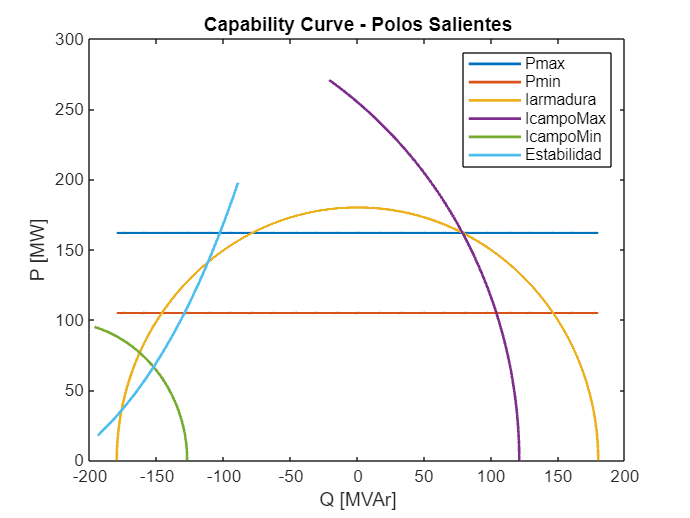

figure(1)
plot(ejexQ,ejeyPn,ejexQ,ejeyPmin,ejexQ,ejeySnominal,ejexEmax,ejeyEmax,ejexEmin,ejeyEmin,Qo1,Po1,'LineWidth',1.5)
title('Capability Curve - Polos Salientes')
xlabel('Q [MVAr]')
ylabel('P [MW]')
legend('Pmax','Pmin','Iarmadura','IcampoMax','IcampoMin','Estabilidad')

## Recursos Adicionales

Si desea conocer otros casos de estudio sobre esta temática puede revisar el File Exchange:

[https://la.mathworks.com/matlabcentral/fileexchange/110095-synchronous-generator-p-q-curve](https://la.mathworks.com/matlabcentral/fileexchange/110095-synchronous-generator-p-q-curve)

## Referencias

Puede considerar las siguientes referencias bibliográficas para profundizar en los conceptos:

[https://circuitglobe.com/capability-curve-of-a-synchronous-generator.html](https://circuitglobe.com/capability-curve-of-a-synchronous-generator.html)

[https://revistapolitecnica.epn.edu.ec/ojs2/index.php/revista_politecnica2/article/view/37](https://revistapolitecnica.epn.edu.ec/ojs2/index.php/revista_politecnica2/article/view/37)